# Pruebas Convertidor

clf;
clc;
clear all;

data = []; % Initialize as empty array
titleName = []; % Initialize as empty string array
imageNames = [];
tName = "";

% 1. Pre-allocate labels as a Cell Array to hold other cell arrays
labels = cell(1, 18); 

%Inputs
for i = 17:34
    %% Title Logic
    if (i<=19) || ( 32<=i && i<=34)
        tName = "Corriente Inductor";   
    elseif ( 20<=i && i<=25) || ( 29<=i && i<=31)
        tName = "Corriente Diodo";
    elseif ( 26<=i && i<=28)
        tName = "Corriente fuente";
    end
    tName = tName + " " + i;   

    imageName = tName + ".png";

    % Store filenames and titles in string arrays
    data = [data, "2025-12-22_Convertidores_4/scope_" + i + ".csv"];
    titleName = [titleName, tName];
    imageNames = [imageNames, imageName];

    % 2. THE FIX: Assign using curly braces {}
    % This places the cell array 'label' inside the i-16th slot of 'labels'
    label = {"Tiempo [s]", "Voltaje de salida [V]", "Corriente [A]", tName, ""};
    labels{i-16} = label;     
    % labels{i} = label; 
end

limits = [NaN, NaN, 4,6, NaN, NaN];
limits32_34 = [NaN, NaN, 4,6, 0, -0.005];

limits_array = {
    limits          limits;
    limits          limits;
    limits          limits;
    limits          limits;
    limits          limits;
    limits          limits;
    limits          limits;
    limits          limits32_34;
    limits32_34     limits32_34;
    };
outputName = lower(replace(imageNames, " ", "_")); % Cleaner way to format filenames

% Fun Fcall
for i = 1:18
    % 3. Pass the content using curly braces
    % plot_scope_data(data(i), labels{i}, limits, outputName(i));
end

%%f16
% i = 26-16;
% plot_scope_data(data(i), labels{i}, [-2e-6,4e-6, 4,6, NaN, NaN], outputName(i));

data = readmatrix('2025-12-22_Convertidores_4/scope_26.csv', 'NumHeaderLines', 2);
time_f16 = data(:, 1);
signal_1_f16 = data(:, 2);
signal_2_f16 = data(:, 5);
signal_2_f16 = movmean(signal_2_f16,16);


%%i33
% i = 33-16;
% plot_scope_data(data(i), labels{i}, [-3e-6,3e-6, 4,6, NaN, NaN], outputName(i));

data = readmatrix('2025-12-22_Convertidores_4/scope_33.csv', 'NumHeaderLines', 2);
time_i33 = data(:, 1);
signal_1_i33 = data(:, 2);
signal_2_i33 = data(:, 5);
signal_2_i33 = movmean(signal_2_i33,16);



% plot_scope_data("Scope_24.csv", ...
%     {"Tiempo [s]", "Voltaje de salida [V]", "Corriente [A]", "Corriente Diodo", ""}, ...
%     limits, "test.png");

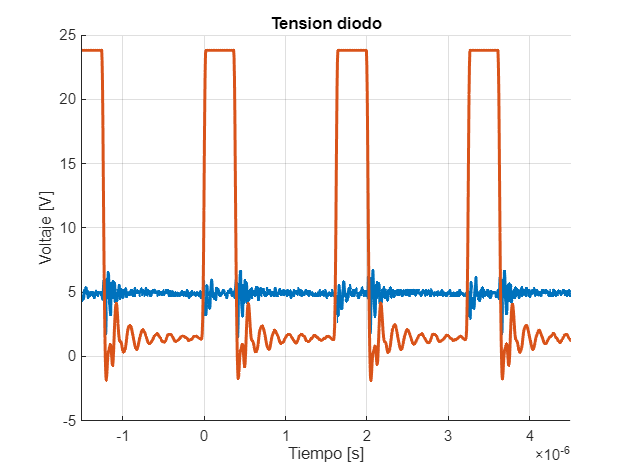

clf

sf = 1.33;

data = readmatrix("2025-12-22_Convertidores_4/scope_22.csv", 'NumHeaderLines', 2);
time_1      = data(:, 1);
volt_1      = data(:, 2);
volt_2      = data(:, 4);
volt_2      = (volt_2 - min(volt_2)/2)* sf ;
volt_2      = movmean(volt_2, 4);
% volt_2      = data(:, 3);
% current_1      = data(:, 3);
% current_1      = current_1 / rSense; %Rsense corriente

clf %% clean figure

figure(13)
hold on 
grid on
plot(time_1,volt_1,'LineStyle', '-', 'LineWidth', 2)
plot(time_1,volt_2,'LineStyle', '-', 'LineWidth', 2)
% ylim([22,22.8]);
ylabel("Voltaje [V]");

xlabel("Tiempo [s]");
xlim([-1.5e-6  4.5e-6])
title("Tension diodo");
% subtitle(plotSubTitle,'FontSize',8);
hold off


% exportgraphics(gcf,"bat_1.png");


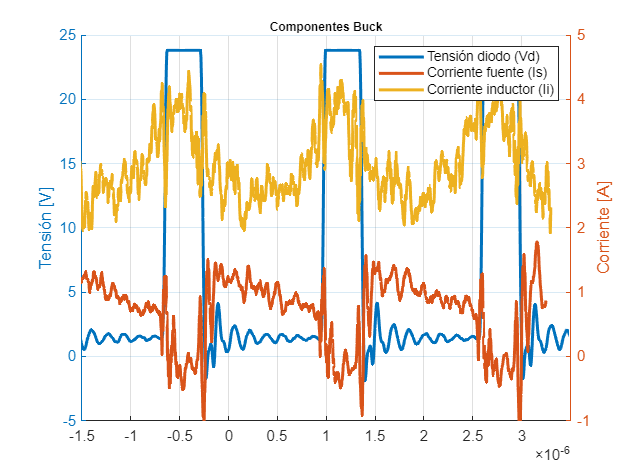

clf %% clean figure

% f16
% i33

yellow_mlab = [0.9290, 0.6940, 0.1250];

figure(14)
hold on 
grid on

yyaxis left
ylabel("Tensión [V]");

%V inductor
time_1 = time_1 - 0.65e-6;
plot(time_1,volt_2,'LineStyle', '-', 'LineWidth', 2)

%I source
yyaxis right
ylabel("Corriente [A]");
signal_2_f16 = signal_2_f16.*100;
plot(time_f16,signal_2_f16,'LineStyle', '-', 'LineWidth', 2)

%I inductor
fc = 1/0.9723;
% fc = 1;
time_i33 = time_i33 + 0.8e-6;
signal_2_i33 = - signal_2_i33.*100.*fc;
plot(time_i33,flip(signal_2_i33),'LineStyle', '-', 'LineWidth', 2, 'Color', yellow_mlab)



    % plot(time, flip(signal2), 'LineStyle', '-', 'LineWidth', 1.5);
    % set(gca, 'YDir','reverse')

ylim([-1, 5]);

% xlabel("Tiempo [s]");
xlim([-1.5e-6  3.5e-6])
title("Componentes Buck",'FontSize',8);
% subtitle(plotSubTitle,'FontSize',8);
legend("Tensión diodo (Vd)", "Corriente fuente (Is)","Corriente inductor (Ii)")
hold off


% exportgraphics(gcf,"buck_char.png");

P_out = rms(signal_2_i33)*5

P_out = 15.1797

P_in = rms(signal_2_f16)*23.8

P_in = 21.5453

dP = P_in - P_out

dP = 6.3656

eff = P_out/P_in

eff = 0.7045


P_out = mean(signal_2_i33)*5

P_out = 14.9177

P_in = mean(signal_2_f16)*24

P_in = 17.3392

dP = P_in - P_out

dP = 2.4215

eff = P_out/P_in

eff = 0.8603

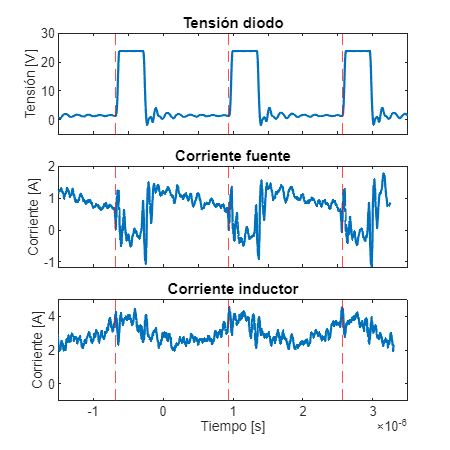


figure(20)
hold on
grid on
tiledlayout("vertical")

xx1 = nexttile;
plot(time_1,volt_2, 'LineWidth', 1.5)
ylabel("Tensión [V]");
ylim([-5 30])
xlim([-1.5e-6  3.5e-6])
title("Tensión diodo",'FontSize',10);
xline(-0.68e-6,'--r');
xline(0.94e-6,'--r');
xline(2.56e-6,'--r');

xx2 = nexttile;
plot(time_f16,signal_2_f16, 'LineWidth', 1.5)
ylabel("Corriente [A]");
xlim([-1.5e-6  3.5e-6])
title("Corriente fuente",'FontSize',10);
xline(-0.68e-6,'--r');
xline(0.94e-6,'--r');
xline(2.56e-6,'--r');

xx3 = nexttile;
plot(time_i33,flip(signal_2_i33), 'LineWidth', 1.5)
ylabel("Corriente [A]");
ylim([-1 5])
xlim([-1.5e-6  3.5e-6])
title("Corriente inductor",'FontSize',10);
xline(-0.68e-6,'--r');
xline(0.94e-6,'--r');
xline(2.56e-6,'--r');

xlabel("Tiempo [s]");
linkaxes([xx1,xx2,xx3],'x');


hold off
% 1. Get the current figure handle
fig = gcf; 

% 2. Set the units and dimensions of the figure
fig.Units = 'pixels';
xticklabels(xx1,{})
xticklabels(xx2,{})
t.TileSpacing = 'compact';
fig.Position = [100, 100, 400, 400]; % [left, bottom, width, height]

% 3. Export without the extra arguments
exportgraphics(fig, "Figuras/buck_char.png");



% Move plots closer together

